# 2D-Fourier Transform

In this section we will implement the 2D Fourier Transform on images and learn about some of its properties.

1. 1 the 2D FFT 

The equations for the FFT and iFFT for an image I of size $M\times N$ are as follows:


$$F\left\lbrace I\left(m,n\right)\right\rbrace \left(u,v\right)=\;\sum_{m=0}^{M-1} \sum_{n=0}^{N-1} I\left(m,n\right)\cdot e^{-2\pi i\left(\frac{u\cdot m}{M}+\frac{v\cdot n}{N}\right)}$$


and the inverse transform:


$$I\left(m,n\right)=\frac{1}{M\cdot N}\sum_{u=0}^{M-1} \sum_{v=0}^{N-1} F\left(u,v\right)\cdot e^{2\pi i\left(\frac{u\cdot m}{M}+\frac{v\cdot n}{N}\right)}$$


accounting to MATLAB's indexing, we will rewrite the array indices as such: 


$$F\left(u+1,v+1\right)=\;\sum_{m=0}^{M-1} \sum_{n=0}^{N-1} I\left(m+1,n+1\right)\cdot e^{-2\pi i\left(\frac{u\cdot m}{M}+\frac{v\cdot n}{N}\right)}$$



$$I\left(m+1,n+1\right)=\frac{1}{M\cdot N}\sum_{u=0}^{M-1} \sum_{v=0}^{N-1} F\left(u+1,v+1\right)\cdot e^{2\pi i\left(\frac{u\cdot m}{M}+\frac{v\cdot n}{N}\right)}$$



$$F\left(u+1,v+1\right)=\;\sum_{m=0}^{M-1} \left(\sum_{n=0}^{N-1} I\left(m+1,n+1\right)\cdot e^{-2\pi i\left(\frac{v\cdot n}{N}\right)} \right)e^{-2\pi i\left(\frac{u\cdot m}{M}\right)}$$


I = imread_normalized("beatles.png");


s =          750        1000



[M,N] = size(I)

M = 750

N = 1000


n = 0:N-1;
m = 0:M-1;

u = 0:M-1;
v = 0:N-1;


um = u'.*m;
vn = v'.*n;

size(um);
size(vn);
e1 = exp(-1i * 2 * pi * (vn/N))

e1 =    1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i
   1.0000 + 0.0000i   1.0000 - 0.0063i   0.9

e2 = exp(-1i * 2 * pi * (um/M))

e2 =    1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i
   1.0000 + 0.0000i   1.0000 - 0.0084i   0.9

sum = I*e1

sum = 1.0e+02 *

   5.0588 + 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i
   5.0588 + 0.0000i  -0.0000 - 0

sum = e2 *sum

sum = 1.0e+05 *

   3.8005 + 0.0000i   0.0350 - 0.1305i   0.0135 + 0.0898i   0.0135 + 0.1219i  -0.0191 - 0.0562i  -0.0541 - 0.0030i   0.0256 + 0.0373i  -0.0025 + 0.0133i   0.0304 - 0.0004i  -0.0026 + 0.0011i  -0.0325 + 0.0272i  -0.0168 - 0.0144i  -0.0013 - 0.0195i  -0.0016 + 0.0051i  -0.0073 + 0.0038i  -0.0015 - 0.0116i   0.0142 + 0.0185i  -0.0135 - 0.0205i  -0.0125 + 0.0013i   0.0087 + 0.0085i   0.0007 + 0.0045i   0.0040 - 0.0012i  -0.0054 - 0.0186i  -0.0056 + 0.0081i  -0.0015 + 0.0103i   0.0003 - 0.0137i   0.0008 + 0.0026i   0.0010 - 0.0027i  -0.0018 - 0.0080i   0.0183 + 0.0003i  -0.0057 - 0.0023i  -0.0070 - 0.0011i   0.0062 + 0.0094i  -0.0007 - 0.0065i  -0.0018 - 0.0004i  -0.0048 - 0.0036i  -0.0041 + 0.0058i   0.0085 - 0.0103i   0.0068 + 0.0012i  -0.0048 + 0.0100i  -0.0011 - 0.0004i   0.0006 + 0.0026i   0.0025 - 0.0001i  -0.0027 + 0.0008i  -0.0072 + 0.0079i   0.0006 - 0.0005i  -0.0025 - 0.0043i   0.0021 - 0.0042i   0.0006 - 0.0002i  -0.0017 + 0.0063i
  -0.0571 + 0.1443i   0.0405 - 0


F = fft2(I)

F = 1.0e+05 *

   3.8005 + 0.0000i   0.0350 - 0.1305i   0.0135 + 0.0898i   0.0135 + 0.1219i  -0.0191 - 0.0562i  -0.0541 - 0.0030i   0.0256 + 0.0373i  -0.0025 + 0.0133i   0.0304 - 0.0004i  -0.0026 + 0.0011i  -0.0325 + 0.0272i  -0.0168 - 0.0144i  -0.0013 - 0.0195i  -0.0016 + 0.0051i  -0.0073 + 0.0038i  -0.0015 - 0.0116i   0.0142 + 0.0185i  -0.0135 - 0.0205i  -0.0125 + 0.0013i   0.0087 + 0.0085i   0.0007 + 0.0045i   0.0040 - 0.0012i  -0.0054 - 0.0186i  -0.0056 + 0.0081i  -0.0015 + 0.0103i   0.0003 - 0.0137i   0.0008 + 0.0026i   0.0010 - 0.0027i  -0.0018 - 0.0080i   0.0183 + 0.0003i  -0.0057 - 0.0023i  -0.0070 - 0.0011i   0.0062 + 0.0094i  -0.0007 - 0.0065i  -0.0018 - 0.0004i  -0.0048 - 0.0036i  -0.0041 + 0.0058i   0.0085 - 0.0103i   0.0068 + 0.0012i  -0.0048 + 0.0100i  -0.0011 - 0.0004i   0.0006 + 0.0026i   0.0025 - 0.0001i  -0.0027 + 0.0008i  -0.0072 + 0.0079i   0.0006 - 0.0005i  -0.0025 - 0.0043i   0.0021 - 0.0042i   0.0006 - 0.0002i  -0.0017 + 0.0063i
  -0.0571 + 0.1443i   0.0405 - 0.1

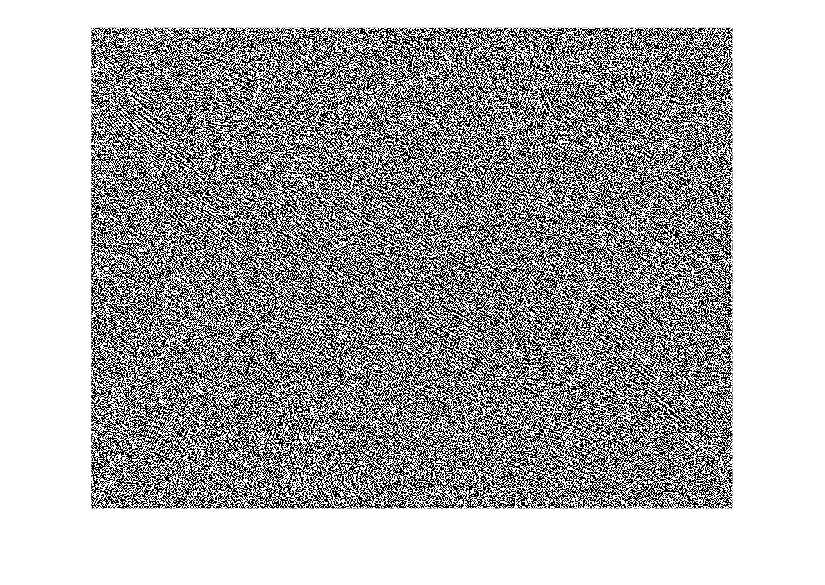

imshow(sum)

imshow(F)

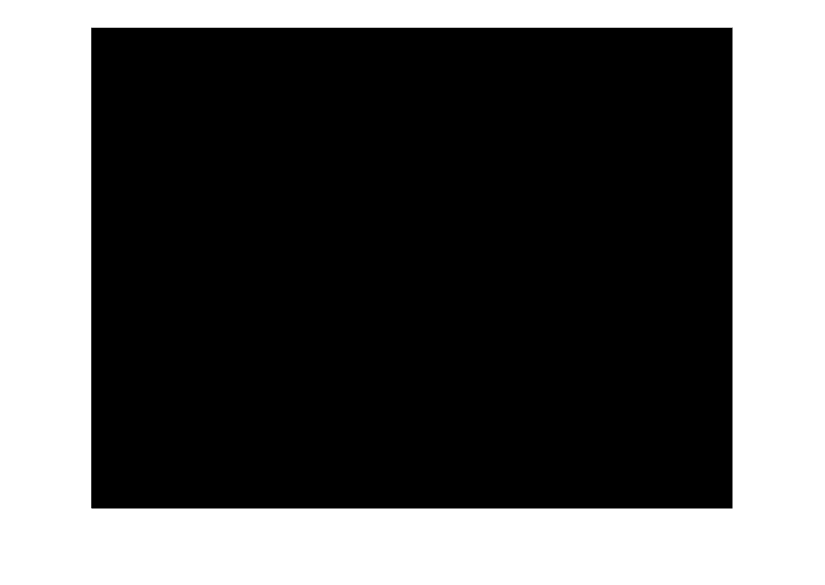

imshow(F-sum)


% init the exponent matrix
